CODE ADDITIONS 

7/8/2026; 7:53 pm (Isaac)

- Implemented an image processing algorithm that (mostly) works for Tube images. It needs testing.

7/9/2026; 4:34 pm (Ryan)

- Updated Dataset organization so that each subfolders organization matches. Changed to imageDatastore and added class labels and pass/fail classification for each image.

7/11/2026; 4:14 pm (Ryan)

- Added corner removal to improve output decision reliability. Added comments to better explain which image is which when selected from the range (Tubes only).

7/12/2026; 10:52 am (Ryan)

- Added labels to ROI that correspond to each table entry for easier analysis of performance. Adjusted minimum eccentricity to improve detection of short tubes as anomalous.

7/12/2026; 3:55 PM (Isaac)

-    Added a function call to the trainingScript() function, defined in trainingScript.mlx; 

7/13/2026; 1:33: PM (Isaac) 

- Changed fileloc to point to the "test" subdirectory within the selected folder we want (in combination with changes to MPDD dataset file structure to have all "categories" of photos in the same location for better AI classifier efficacy)

7/13/2026; 3:26 PM (Isaac)

- Implemented displayInspectionOutput.m to format output in a cleaner, easier to interpret result for the user.

- (TO-DO: Remove previous outputs from singleImageInspectionFunction.mlx and fine tune output from displayInspectionOutput.m)

- Added conditional branch to run training() function (i.e. for training AI classifier) depending on presence of tubeClassifierNet.mat in working directory

Choose Data Subset of Interest

dataSubset = "tubes";
displayOrginalImage = true;

Current working algorithm

numObsPerClass = 4×2 table
         Label          Count
    ________________    _____

    color_mismatch        8  
    defective_length     13  
    good                 32  
    malformed_metal      50  


Number of Files: 103


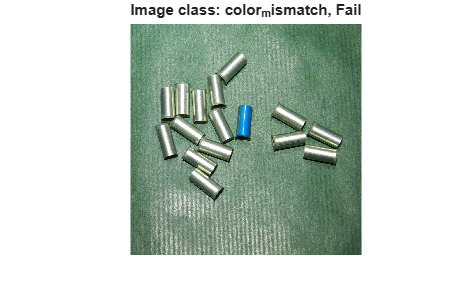

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
%
% To change your active path, click the "Set Path" option under the
% "Environment" sub tab within the MATLAB application. 
fileLoc = sprintf("MPDD/%s/test", dataSubset);


% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Filter 'ground truth'/masks that are only used for model verification
excludeMask = contains(ds.Files, "gt*" | "mask");
ds = subset(ds, ~excludeMask);

% Obtain the number of files within the selected sub directory
numFiles = numel(ds.Files);

% ***Image processing begins here***
%
% Load the image of interest from the datastore object
% Color mismatch    01 - 008, + 21
% Defective Length  09 - 021
% Malformed Metal   22 - 071, + 8
% Good              72 - 225
imgNum = 5;
img = readimage(ds, imgNum);

% Labels image and (Optionally) Displays class & image info
% imgClass <-- Official label of the image
% imgPF <-- Whether or not the part would pass or fail
imgClass =  ds.Labels(imgNum); 
if imgClass ~= "good"
    imgPF = "Fail"; 
else
    imgPF = "Pass";
end

if displayOrginalImage
    numObsPerClass = countEachLabel(ds)
    imgInfo = sprintf("Image class: %s, %s", imgClass, imgPF);

    disp("Number of Files: " + numFiles);
    imshow(img);
    title(imgInfo);
end

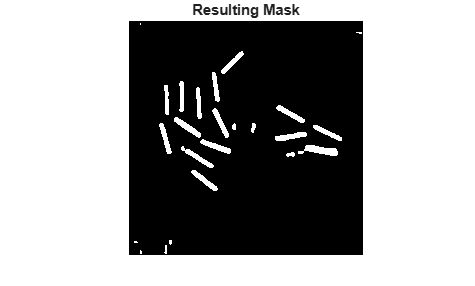

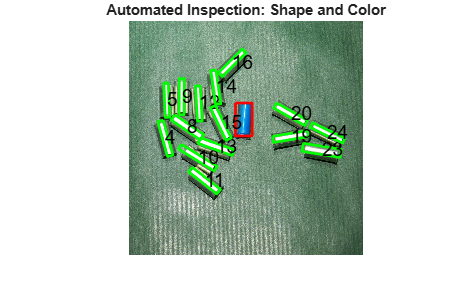

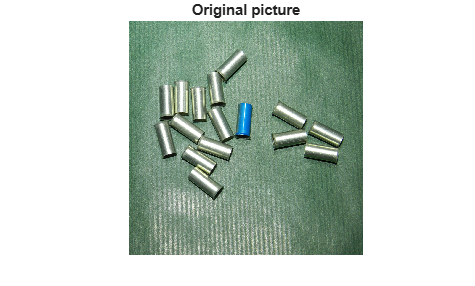

Average Tube Area:      1783.70
Average Tube Eccentricity: 0.95

    Area        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Num
    ____    ________________    _______________    _______________    ____________    ___________    ___

     148    30.676    968.99        18.035             10.908           0.79636         -4.5035       1 
       9        51        14        10.392             1.1547           0.99381              90       2 
      85    53.129    1011.7        17.973              6.353           0.93544         -86.303       3 
    2965    159.52    514.19        159.16             24.696           0.98789          -74.42       4 
    2208    165.54    346.81        151.08             19.776     

aiScores =     1.0000    0.0000    0.0000    0.0000


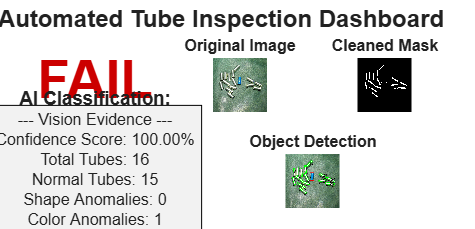


% Inspect the image and print out a report
singleImageInspectionFunction(img);


% call the trainingScript function to train the AI classifier based on
% whether tubeClassifierNet.mat is defined/present in the working
% directory. 
%
% If present, the training function will not run;
% Otherwise, the training function will run to generate a new
% tubeClassifierNet.mat file for use in the singleImageInspectionFunction()
if isfile("tubeClassifierNet.mat")
    disp("Trained AI model found ('tubeClassifierNet.mat'). Skipping training phase.");
else
    disp("No trained AI model found. Initiating training phase...");
    training(ds); 
end

Trained AI model found ('tubeClassifierNet.mat'). Skipping training phase.
